# One-Legged Hopping Robot

#### Parameters

clear all;
close all;
clc

M1=1; % Leg mass [kg]
M2=10; % Body mass [kg]

I1=1; % Leg moment of Inertia [kg-m^2]
I2=10; %Body moment of Inertia [kg-m^2]

r1=0.5; % [m]
r2=0.4; % [m]

k0=1; % [m]
KL=10^3; % [Nt/m]

KL2=60000; % [Nt/m]
BL2=220; % [Nt-s/m]

KG=10^4; % [Nt/m]
BG=75; % [Nt-s/m]

g=9.8;

#### Initial Conditions

chi_0 = 0.07;

ini_theta1=0;
ini_theta1_d=0;

ini_theta2=0;
ini_theta2_d=0;

ini_w=k0 - chi_0;
ini_w_d=0;

ini_x0=0;
ini_x0_d=0;

ini_y0=0.5;
ini_y0_d=0;

ini_x1=ini_x0+r1*sin(ini_theta1);
ini_x1_d=0;

ini_y1=ini_y0+r1*cos(ini_theta1);
ini_y1_d=0;

ini_x2=ini_x1+r2*sin(ini_theta2);
ini_x2_d=0;

ini_y2=ini_y0+ini_w+r2*cos(ini_theta2);
ini_y2_d=0;



#### Theta1_desired for torque control (equation 1)

theta1_des=0;

**Desired system energy to jump to height H (equation 14)**

H=0.5; %[m]
H2=0.5; %[m]
H3=0.5; %[m]
H4=0.5; %[m]
H5=0.5; %[m]
H6=0.4; %[m]
H7=0.4; %[m]
H8=0.4; %[m]

T2_change = 10; % Time at which the height reference is changed [s]
T3_change = 20; % Time at which the height reference is changed [s]
T4_change = 30; % Time at which the height reference is changed [s]
T5_change = 40; % Time at which the height reference is changed [s]
T6_change = 50; % Time at which the height reference is changed [s]
T7_change = 60; % Time at which the height reference is changed [s]
T8_change = 70; % Time at which the height reference is changed [s]


desired_energy = M1*g*(H+r1) + M2*g*(H+k0+r2);
desired_energy2 = M1*g*(H2+r1) + M2*g*(H2+k0+r2);
desired_energy3 = M1*g*(H3+r1) + M2*g*(H3+k0+r2);
desired_energy4 = M1*g*(H4+r1) + M2*g*(H4+k0+r2);
desired_energy5 = M1*g*(H5+r1) + M2*g*(H5+k0+r2);
desired_energy6 = M1*g*(H6+r1) + M2*g*(H6+k0+r2);
desired_energy7 = M1*g*(H7+r1) + M2*g*(H7+k0+r2);
desired_energy8 = M1*g*(H8+r1) + M2*g*(H8+k0+r2);

**SIMULINK**

simtime=12; %simulation time
warning('off')
ini_y0=H;
x2_desired_1 = 0.7;
start_1 = 0;
x2_desired_2 = 0;
start_2 = 30;
x2_desired_3 = 0;
start_3 = 60;
SimDec=sim('HoppingModel_Sweeping_TD',simtime); %Execution of the simulation in Simulink

Found algebraic loop containing: 
HoppingModel_Sweeping_TD/One_Legged_Robot/Subsystem_x/Fcn (algebraic variable)
HoppingModel_Sweeping_TD/One_Legged_Robot/Subsystem_x/x_dd
HoppingModel_Sweeping_TD/One_Legged_Robot/Subsystem_y/Fcn
HoppingModel_Sweeping_TD/One_Legged_Robot/Subsystem_y/y_dd
HoppingModel_Sweeping_TD/One_Legged_Robot/Subsystem_w/Fcn


Plot of y0,y1,y2 with chi

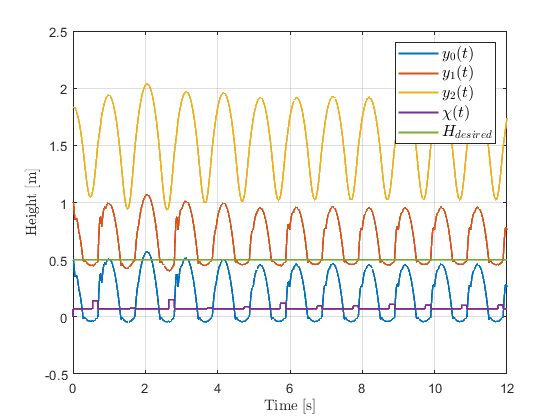

figure(1)
plot(y0.time, y0.data,'Linewidth',1.5)
hold on
plot(y1.time, y1.data,'Linewidth',1.5)
hold on
plot(y2.time, y2.data,'Linewidth',1.5)
hold on
plot(chi.time, chi.data,'Linewidth',1.5)
grid on
plot(Desired_H.time,Desired_H.data,'Linewidth',1.5)
grid on
%ylim([-0.1 2.5])
xlabel('Time [s]','Interpreter','latex')
ylabel('Height [m]','Interpreter','latex')
legend('$y_{0}(t)$','$y_{1}(t)$','$y_{2}(t)$','$\chi(t)$','$H_{desired}$','Fontsize',12,'Interpreter','latex')

Plot of x2

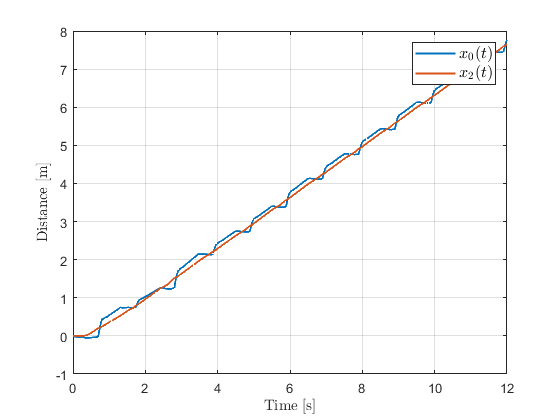

figure(2)
plot(x0.time, x0.data,'Linewidth',1.5)
hold on
plot(x2.time, x2.data,'Linewidth',1.5)
%hold on
%plot(Desired_x2.time, Desired_x2.data,'Linewidth',1.5)
grid on
xlabel('Time [s]','Interpreter','latex')
ylabel('Distance [m]','Interpreter','latex')
legend('$x_{0}(t)$','$x_{2}(t)$','$x_{2,desired}(t)$','Fontsize',12,'Interpreter','latex')

Plot of x2_dot

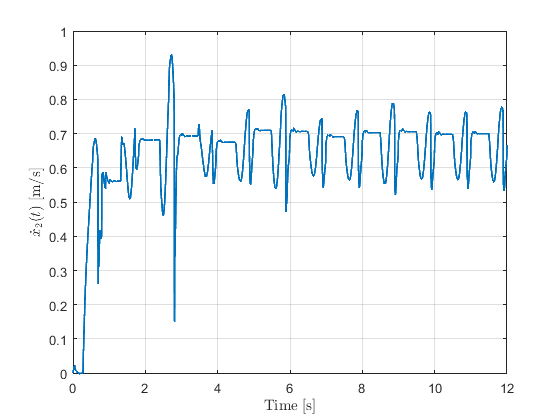

figure(3)
plot(x2d.time, x2d.data,'Linewidth',1.5)
grid on
xlabel('Time [s]','Interpreter','latex')
ylabel('$\dot{x}_{2}(t)$ [m/s]','Interpreter','latex')

%ylim([-0.01 0.08])

Plot of theta1 and theta 2

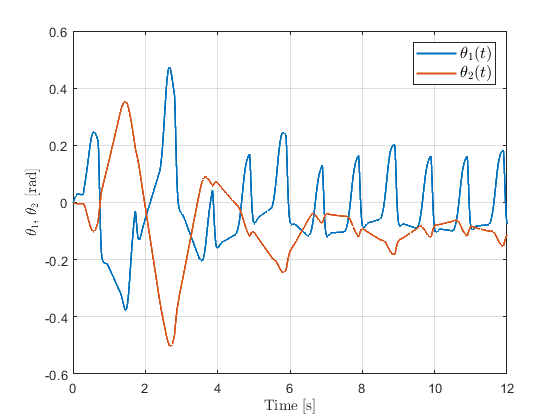

figure(4)
plot(theta1.time, theta1.data,'Linewidth',1.5)
hold on
plot(theta2.time, theta2.data,'Linewidth',1.5)
grid on
xlabel('Time [s]','Interpreter','latex')
ylabel('$\theta_1$, $\theta_2$ [rad]','Interpreter','latex')
legend('$\theta_{1}(t)$','$\theta_{2}(t)$','Fontsize',12,'Interpreter','latex')

Plot of theta2d

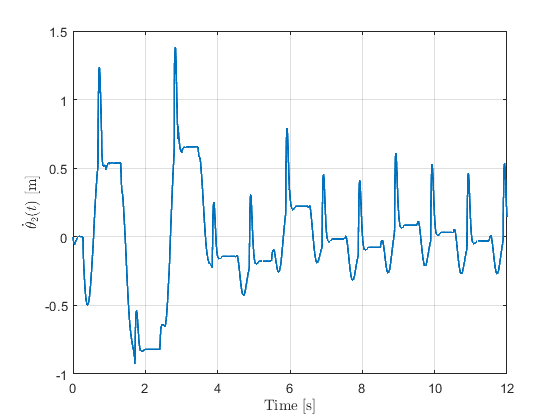

figure(8)
plot(theta2d.time, theta2d.data,'Linewidth',1.5)
grid on
xlabel('Time [s]','Interpreter','latex')
ylabel('$\dot{\theta}_{2}(t)$  [m]','Interpreter','latex')

Plot of theta1_control

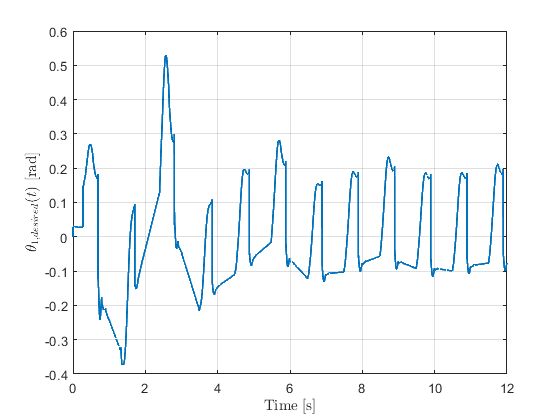

figure(6)
plot(theta1_control.time, theta1_control.data,'Linewidth',1.5)
grid on
xlabel('Time [s]','Interpreter','latex')
ylabel('$\theta_{1,desired}(t)$  [rad]','Interpreter','latex')

Plot of tau

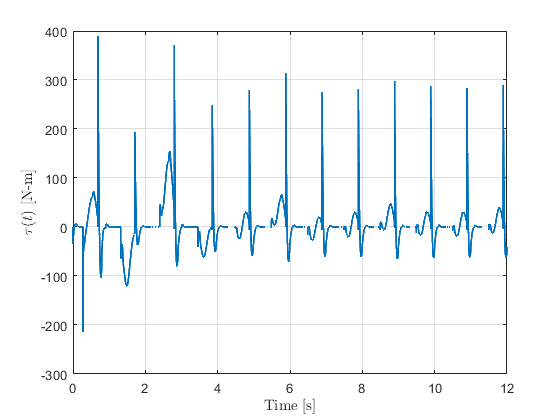

figure(7)
plot(tau.time, tau.data,'Linewidth',1.5)
grid on
xlabel('Time [s]','Interpreter','latex')
ylabel('$\tau(t)$  [N-m]','Interpreter','latex')

Plot of xTD

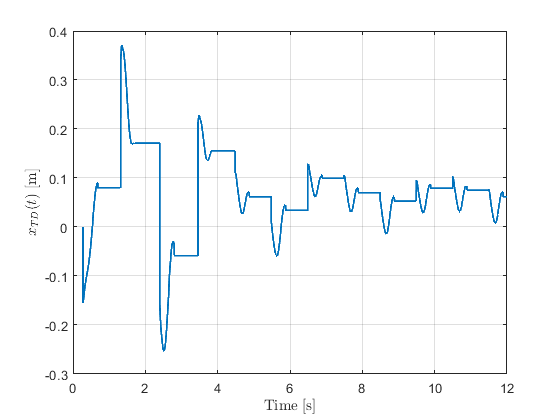

figure(8)
plot(xTD.time, xTD.data,'Linewidth',1.5)
grid on
xlabel('Time [s]','Interpreter','latex')
ylabel('$x_{TD}(t)$  [m]','Interpreter','latex')

Plot of xTD + wsintheta1

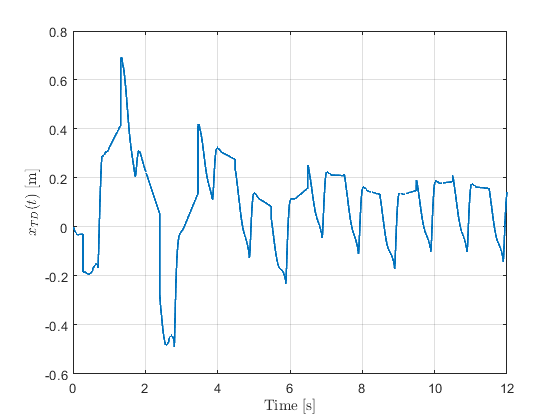

figure(8)
plot(xTD.time, xTD.data - wsintheta1.data,'Linewidth',1.5)
grid on
xlabel('Time [s]','Interpreter','latex')
ylabel('$x_{TD}(t)$  [m]','Interpreter','latex')